## Estimate model from square wave, validate with sine wave

Hyperparams

clear
% this program has to be run from within functions folder!
% cd ..;
trainingType = "sine";
validationType = "squareWave";
output = "pendulum";
dataDirectory = output;

trainingStruct = load(strcat("importData/", trainingType, ".mat"));
validationStruct = load(strcat("importData/", validationType, ".mat"));

% sampling time
Ts = 0.002;

Preprocessing: cut off a few seconds

secondsToCutOff =0;
% like this because matlab passes by value
trainingStruct = cutoffBeginning(trainingStruct, Ts, secondsToCutOff);
validationStruct = cutoffBeginning(validationStruct, Ts, secondsToCutOff);
% set options appropriately
tfestOpt = tfestOptions;
ssestOpt = ssestOptions;
initialCondZero = false;
if secondsToCutOff == 0
    initialCondZero = true;
    tfestOpt.InitialCondition = 'zero';
    ssestOpt.InitialState = 'zero';
else 
    dataDirectory = strcat(dataDirectory, "/cutoff");
end

load training and validation data

[t, y, u] = extractData(trainingStruct, output);
[t_val, y_val, u_val] = extractData(validationStruct, output);

data = iddata(y, u, Ts);
data_val = iddata(y_val, u_val, Ts);

% augment training data
extraTrainingData = false;
if extraTrainingData
    extraDataStruct = load("tower_crane_emile_lennart_data.mat");
    [to, yo, uo] = extractData(extraDataStruct, output);
    extraData = iddata(yo, uo, Ts);
    data = merge(data, extraData);
end

armToPendulum = false;
if armToPendulum
    dataDirectory = strcat(dataDirectory, "/armToPendulum");
    data = getArmToPendulumData(trainingStruct, Ts);
    data_val = getArmToPendulumData(validationStruct, Ts);
end

constants

N = length(t);
% why this line?
t = (0:Ts:(N-1)*Ts)';

trainingData = data;
mergeTrainingAndValData = false;
if mergeTrainingAndValData
    dataDirectory = strcat(dataDirectory, "/doubleData");
    trainingData = merge(data_val, data);
else 
    dataDirectory = strcat(dataDirectory, "/", trainingType);
end

Create data and estimate transfer function

numberPoles = 3

numberPoles = 3



%Gest = tfest(data, 3, 1, 0, opt)
% only specify number of poles
Gest = tfest(trainingData, numberPoles, tfestOpt)

Gest =
 
  From input "u1" to output "y1":
   0.9218 s^2 - 36.29 s + 33.84
  -------------------------------
  s^3 + 3.378 s^2 + 227 s + 438.5
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 3   Number of zeros: 2
   Number of free coefficients: 6
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                  
Estimated using TFEST on time domain data "trainingData".
Fit to estimation data: 92.34%                           
FPE: 0.0001036, MSE: 0.0001034                           


See fit on training data

% current data directory
cdd = strcat(dataDirectory, "/tfest");
myCompare(data, Gest, initialCondZero, cdd, strcat("/train_np", int2str(numberPoles)));

./dataSoftlink/pendulum/sine/tfest/train_np3.txt


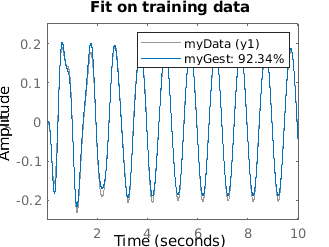

title('Fit on training data')

See fit on validation data

myCompare(data_val, Gest, initialCondZero, cdd, strcat("/val_np", int2str(numberPoles)))

./dataSoftlink/pendulum/sine/tfest/val_np3.txt


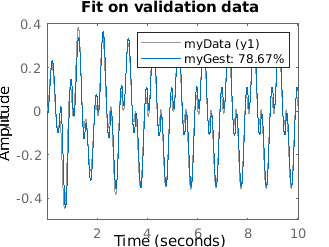

title('Fit on validation data')

Estimate model with ssest

cdd = strcat(dataDirectory, "/ssest");
% telling initial state is zero in the options
Gss = ssest(trainingData, 1:10, ssestOpt);
Gest_new = tf(Gss)

Gest_new =
 
  From input "u1" to output "y1":
    -1.197 s - 15.74
  ---------------------
  s^2 + 2.915 s + 131.7
 
Continuous-time transfer function.



% setting initial conditions to false might not be true
myCompare(data, Gest_new, false, cdd, "/train");

./dataSoftlink/pendulum/sine/ssest/train.txt


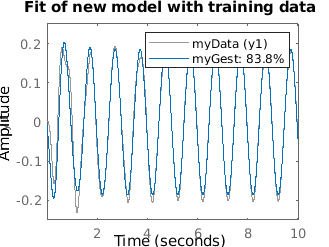

title('Fit of new model with training data');

myCompare(data_val, Gest_new, false, cdd, "/val");

./dataSoftlink/pendulum/sine/ssest/val.txt


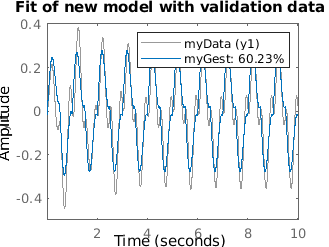

title('Fit of new model with validation data');

if we cut something off for training, compare the obtained model with the entire data

cdd = strcat(cdd, "uncutoff");
if not(initialCondZero) 
    skipSec = 0
    [t_c, y_c, u_c] = extractCompleteData(trainingStruct, output, Ts, skipSec);
    [t_c_val, y_c_val, u_c_val] = extractCompleteData(validationStruct, output, Ts, skipSec);
    % TODO modular if arm or pendulum
    data_c = iddata(y_c, u_c, Ts);
    data_c_val = iddata(y_c_val, u_c_val, Ts);
    figure
    myCompare(data_c, Gest_new, skipSec == 0, cdd, "/train")
    title('Fit of model trained with cutoff data with the complete data')
    
    figure
    myCompare(data_c_val, Gest_new, skipSec == 0, cdd, "/val")
    title('Fit of model trained with cutoff data with the complete data (validation)')
end

Sanity check : system response to constant zero input

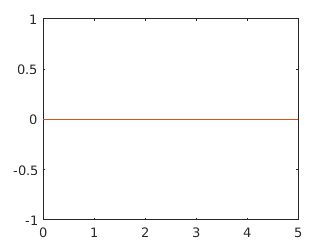

time = 0:Ts:5;
zero_input = zeros(length(time), 1);
zero_response = lsim(Gest, zero_input, time);
zero_response_new = lsim(Gest_new, zero_input, time);

plot(time, [zero_input, zero_response])

plot(time, [zero_input, zero_response_new])

extract complete data in case the normal data is cut off

function result = getArmToPendulumData(dataStruct, Ts)
    data_crane = dataStruct.data_crane;
    y_arm = data_crane(2, :)';
    y_pendulum = data_crane(3, :)';
    result = iddata(y_pendulum, y_arm, Ts);
end

Compare with initial conditions as potentially zero

function myCompare(myData, myGest, initialCondZero, directory, filename)
    % prepare to store data in .txt
    path = strcat('./dataSoftlink/', directory);
    % hide warning if directory already exists
    [ ~, ~ ] = mkdir(path);
    fitValuePostfix = '_fit';
    ending = '.txt';
    
    opt = compareOptions;
    if initialCondZero
        opt.InitialCondition = 'zero';
    end
    compare(myData, myGest, opt);  
    % save to two text files as well
    [ymod, fit, ~] = compare(myData, myGest, opt);
    % time vector
    time = myData.Ts * (0:length(myData.y) - 1)';
    % save one value, skip ... other ones
    skips = 9;
    toSave = [time myData.u myData.y ymod.y];
    toSave = toSave(1:skips + 1:size(toSave, 1), :);
    % save files
    completeFilename = strcat(path, filename, ending);
    disp(completeFilename);
    completeFilenameFit = strcat(path, filename, fitValuePostfix, ending);
    writelines("t u yreal yest", completeFilename);
    writematrix(toSave, completeFilename, 'Delimiter', 'space', 'WriteMode','append');
    writematrix(round(fit, 1), completeFilenameFit, 'Delimiter', 'space');
end

cutoff transitory response

function result = cutoffBeginning(dataStruct, Ts, secondsToCutOff)
    if secondsToCutOff > 0
    dataStruct.data_crane_complete = dataStruct.data_crane;
    dataStruct.data_crane = dataStruct.data_crane(1:end, round(secondsToCutOff / Ts) + 1 : end);
    end
    result = dataStruct;
end